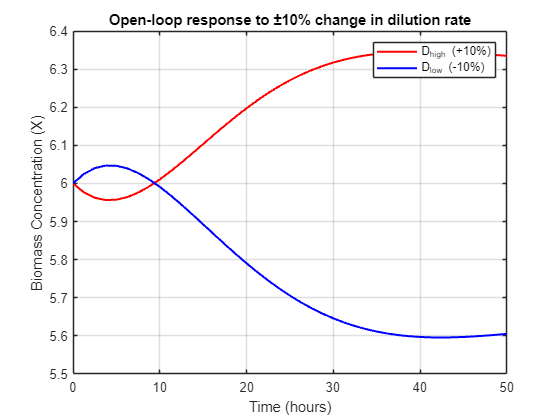

% Define parameters for the fermentation model
mu_m = 0.48; % 1/h, maximum specific growth rate
P_m = 50; % g/L, product inhibition constant
K_m = 1.2; % g/L, Monod constant
K_i = 22; % g/L, inhibition constant for substrate
alpha = 2.2; % g/g, product yield coefficient
beta = 0.2; % 1/h, maintenance rate
Y_XS = 0.4; % g/g, yield coefficient

% Nominal dilution rate for the operating point
D_nominal = 0.0389; % hr^-1
perturbation = 0.1; % 10% change

% New dilution rates for testing
D_high = D_nominal * (1 + perturbation);
D_low = D_nominal * (1 - perturbation);

% Time span for simulation
time_span = [0, 50]; % hours

% Initial conditions for the state variables [X, S, P]
initial_conditions = [6, 5, 44.04]; % Initial steady-state values for [X, S, P]

% Define the mu function as a nested function within the script
mu_function = @(S, P) mu_m * (1 - P / P_m) * (S / (K_m + S + (S^2) / K_i));

% Define the system of ODEs as a function of time, state vector, and dilution rate
system_ode = @(t, Y, D) [
    -D * Y(1) + mu_function(Y(2), Y(3)) * Y(1); % dX/dt: Biomass concentration
    D * (20 - Y(2)) - (1 / Y_XS) * mu_function(Y(2), Y(3)) * Y(1); % dS/dt: Substrate concentration
    -D * Y(3) + (alpha * mu_function(Y(2), Y(3)) + beta) * Y(1) % dP/dt: Product concentration
];

% Simulate the system for D_high
[t_high, Y_high] = ode45(@(t, Y) system_ode(t, Y, D_high), time_span, initial_conditions);

% Simulate the system for D_low
[t_low, Y_low] = ode45(@(t, Y) system_ode(t, Y, D_low), time_span, initial_conditions);

% Plot the results for biomass concentration (X) over time
figure;
plot(t_high, Y_high(:, 1), 'r', 'LineWidth', 1.5); % Red line for D_high
hold on;
plot(t_low, Y_low(:, 1), 'b', 'LineWidth', 1.5); % Blue line for D_low
xlabel('Time (hours)');
ylabel('Biomass Concentration (X)');
legend('D_{high} (+10%)', 'D_{low} (-10%)');
title('Open-loop response to ±10% change in dilution rate');
grid on;

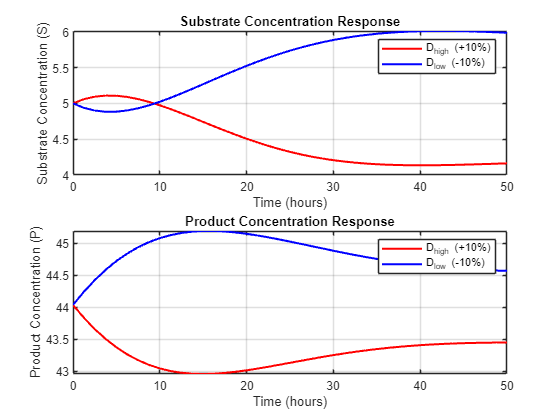


% Additional plots for substrate (S) and product (P) concentrations
figure;
subplot(2, 1, 1);
plot(t_high, Y_high(:, 2), 'r', 'LineWidth', 1.5); % Substrate (S) for D_high
hold on;
plot(t_low, Y_low(:, 2), 'b', 'LineWidth', 1.5); % Substrate (S) for D_low
xlabel('Time (hours)');
ylabel('Substrate Concentration (S)');
legend('D_{high} (+10%)', 'D_{low} (-10%)');
title('Substrate Concentration Response');
grid on;

subplot(2, 1, 2);
plot(t_high, Y_high(:, 3), 'r', 'LineWidth', 1.5); % Product (P) for D_high
hold on;
plot(t_low, Y_low(:, 3), 'b', 'LineWidth', 1.5); % Product (P) for D_low
xlabel('Time (hours)');
ylabel('Product Concentration (P)');
legend('D_{high} (+10%)', 'D_{low} (-10%)');
title('Product Concentration Response');
grid on;